# Data Processing - Remove Regeneration - ARIMA 분석 - #5 #6을 사용하자

clear % 이전 그래프는 지우지 않는다.
close all %  이전 그래프는 지운다.
load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat

load B0029.mat
load B0030.mat
load B0031.mat
load B0032.mat

load B0033.mat
load B0034.mat
load B0036.mat

cap05 = extract_discharge(B0005);
cap06 = extract_discharge(B0006);
cap07 = extract_discharge(B0007);
cap18 = extract_discharge(B0018);

cap29  = extract_discharge(B0029);
cap30  = extract_discharge(B0030);
cap31  = extract_discharge(B0031);
cap32  = extract_discharge(B0032);

cap33 = extract_discharge(B0033);
cap34 = extract_discharge(B0034);
cap36 = extract_discharge(B0036);

% A set of four Li-ion batteries (# 5, 6, 7 and 18) 
% were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).


#### room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V = 33번 측정이상이 있음.

Data Description:

A set of three Li-ion batteries (# 33, 34 and 36) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature (24 deg C). Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A** until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively. For **battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

Files:

B0033.mat	Data for Battery #33

B0034.mat	Data for Battery #34

B0036.mat	Data for Battery #36

%  (24 deg C). 
% Charging was carried out in a constant current (CC) mode at 1.5A 
% until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode 
% until the charge current dropped to 20mA. 
% Discharge was carried out at 4A until the battery voltage fell to 2.0V and 2.2V 
% for batteries 33 and 34 respectively. 
% For battery 36 discharge was done at 2A until voltage fell to 2.7V. 

%result = [cap',cycleTimeHour',restTimeHour',restCycle',cCCEndTimeSec',cTempMaxDt',cCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dCcEndTimeSec' ];
%result = [cap',cycleTimeHourHour',restTimeHourHour',restCycle',cTempMax',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',cCcEndTimeSec',dCcEndTimeSec' ];
%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cCcEndTimeSec',dTempMax',dCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe' ];

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;

pattern_temp05_const = 24;
pattern_temp06_const = 24;
pattern_temp07_const = 24;
pattern_temp18_const = 24;
pattern_temp29_const = 43;
pattern_temp30_const = 43;
pattern_temp31_const = 43;
pattern_temp32_const = 43;
pattern_temp33_const = 24;
pattern_temp34_const = 24;
pattern_temp36_const = 24;

pattern_CC_amps05_const = 2;
pattern_CC_amps06_const = 2;
pattern_CC_amps07_const = 2;
pattern_CC_amps18_const = 2;
pattern_CC_amps29_const = 4;
pattern_CC_amps30_const = 4;
pattern_CC_amps31_const = 4;
pattern_CC_amps32_const = 4;
pattern_CC_amps33_const = 4;
pattern_CC_amps34_const = 4;
pattern_CC_amps36_const = 2;

pattern_dVolt05_const = 4.2 - 2.7 ; 
pattern_dVolt06_const = 4.2 - 2.5 ; 
pattern_dVolt07_const = 4.2 - 2.2 ; 
pattern_dVolt18_const = 4.2 - 2.5 ; 
pattern_dVolt29_const = 4.2 - 2.0 ;   
pattern_dVolt30_const = 4.2 - 2.2 ;   
pattern_dVolt31_const = 4.2 - 2.5 ;   
pattern_dVolt32_const = 4.2 - 2.7 ;   
pattern_dVolt33_const = 4.2 - 2.0 ; 
pattern_dVolt34_const = 4.2 - 2.2 ; 
pattern_dVolt36_const = 4.2 - 2.7 ; 



result_05 = extract_feature_all_v2(B0005,0,cap05);
result_06 = extract_feature_all_v2(B0006,0,cap06);
result_07 = extract_feature_all_v2(B0007,0,cap07);
result_18 = extract_feature_all_v2(B0018,0,cap18);
result_29 = extract_feature_all_v2(B0029,0,cap29);
result_30 = extract_feature_all_v2(B0030,0,cap30);
result_31 = extract_feature_all_v2(B0031,0,cap31);
result_32 = extract_feature_all_v2(B0032,0,cap32);
result_33 = extract_feature_all_v2(B0033,0,cap33);
result_34 = extract_feature_all_v2(B0034,0,cap34);
result_36 = extract_feature_all_v2(B0036,0,cap36);



pattern_dVolt_vector   = ones(length(result_05),1) *  pattern_dVolt05_const; result_05 = [result_05,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_06),1) *  pattern_dVolt06_const; result_06 = [result_06,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_07),1) *  pattern_dVolt07_const; result_07 = [result_07,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_18),1) *  pattern_dVolt18_const; result_18 = [result_18,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_29),1) *  pattern_dVolt29_const; result_29 = [result_29,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_30),1) *  pattern_dVolt30_const; result_30 = [result_30,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_31),1) *  pattern_dVolt31_const; result_31 = [result_31,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_32),1) *  pattern_dVolt32_const; result_32 = [result_32,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_33),1) *  pattern_dVolt33_const; result_33 = [result_33,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_34),1) *  pattern_dVolt34_const; result_34 = [result_34,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_36),1) *  pattern_dVolt36_const; result_36 = [result_36,pattern_dVolt_vector];

pattern_temp_vector   = ones(length(result_05),1) *  pattern_temp05_const; result_05 = [result_05,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_06),1) *  pattern_temp06_const; result_06 = [result_06,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_07),1) *  pattern_temp07_const; result_07 = [result_07,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_18),1) *  pattern_temp18_const; result_18 = [result_18,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_29),1) *  pattern_temp29_const; result_29 = [result_29,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_30),1) *  pattern_temp30_const; result_30 = [result_30,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_31),1) *  pattern_temp31_const; result_31 = [result_31,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_32),1) *  pattern_temp32_const; result_32 = [result_32,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_33),1) *  pattern_temp33_const; result_33 = [result_33,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_34),1) *  pattern_temp34_const; result_34 = [result_34,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_36),1) *  pattern_temp36_const; result_36 = [result_36,pattern_temp_vector];


pattern_CC_amps_vector   = ones(length(result_05),1) *  pattern_CC_amps05_const; result_05 = [result_05,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_06),1) *  pattern_CC_amps06_const; result_06 = [result_06,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_07),1) *  pattern_CC_amps07_const; result_07 = [result_07,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_18),1) *  pattern_CC_amps18_const; result_18 = [result_18,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_29),1) *  pattern_CC_amps29_const; result_29 = [result_29,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_30),1) *  pattern_CC_amps30_const; result_30 = [result_30,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_31),1) *  pattern_CC_amps31_const; result_31 = [result_31,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_32),1) *  pattern_CC_amps32_const; result_32 = [result_32,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_33),1) *  pattern_CC_amps33_const; result_33 = [result_33,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_34),1) *  pattern_CC_amps34_const; result_34 = [result_34,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_36),1) *  pattern_CC_amps36_const; result_36 = [result_36,pattern_CC_amps_vector];


## remove rest cycle

%{
restCycleTF_raw_index = find (result_05(:,restCycleIdx) == 1 )'; result_05(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_06(:,restCycleIdx) == 1 )'; result_06(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_07(:,restCycleIdx) == 1 )'; result_07(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_18(:,restCycleIdx) == 1 )'; result_18(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_29(:,restCycleIdx) == 1 )'; result_29(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_30(:,restCycleIdx) == 1 )'; result_30(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_31(:,restCycleIdx) == 1 )'; result_31(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_32(:,restCycleIdx) == 1 )'; result_32(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_33(:,restCycleIdx) == 1 )'; result_33(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_34(:,restCycleIdx) == 1 )'; result_34(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_36(:,restCycleIdx) == 1 )'; result_36(restCycleTF_raw_index,:)=[];
%}



               
i = 1;
capacity05 = result_05(:,i); 
capacity06 = result_06(:,i); 
capacity07 = result_07(:,i); 
capacity18 = result_18(:,i); 
capacity29 = result_29(:,i); 
capacity30 = result_30(:,i); 
capacity31 = result_31(:,i); 
capacity32 = result_32(:,i); 
capacity33 = result_33(:,i); 
capacity34 = result_34(:,i); 
capacity36 = result_36(:,i); 

% base is 2V 
capacityNorm05 = result_05(:,i) + 2 - result_05(1,i); 
capacityNorm06 = result_06(:,i) + 2 - result_06(1,i); 
capacityNorm07 = result_07(:,i) + 2 - result_07(1,i); 
capacityNorm18 = result_18(:,i) + 2 - result_18(1,i); 
capacityNorm29 = result_29(:,i) + 2 - result_29(1,i); 
capacityNorm30 = result_30(:,i) + 2 - result_30(1,i); 
capacityNorm31 = result_31(:,i) + 2 - result_31(1,i); 
capacityNorm32 = result_32(:,i) + 2 - result_32(1,i); 
capacityNorm33 = result_33(:,i) + 2 - result_33(1,i); 
capacityNorm34 = result_34(:,i) + 2 - result_34(1,i); 
capacityNorm36 = result_36(:,i) + 2 - result_36(1,i); 

i =  i + 1;
cycleTimeHour05 = result_05(:,i); 
cycleTimeHour06 = result_06(:,i); 
cycleTimeHour07 = result_07(:,i); 
cycleTimeHour18 = result_18(:,i); 
cycleTimeHour29 = result_29(:,i); 
cycleTimeHour30 = result_30(:,i); 
cycleTimeHour31 = result_31(:,i); 
cycleTimeHour32 = result_32(:,i); 
cycleTimeHour33 = result_33(:,i); 
cycleTimeHour34 = result_34(:,i); 
cycleTimeHour36 = result_36(:,i); 

i =  i + 1;
restTimeHour05 = result_05(:,i); 
restTimeHour06 = result_06(:,i); 
restTimeHour07 = result_07(:,i); 
restTimeHour18 = result_18(:,i); 
restTimeHour29 = result_29(:,i); 
restTimeHour30 = result_30(:,i); 
restTimeHour31 = result_31(:,i); 
restTimeHour32 = result_32(:,i); 
restTimeHour33 = result_33(:,i); 
restTimeHour34 = result_34(:,i); 
restTimeHour36 = result_36(:,i); 

i =  i + 1;
restCycle05 = result_05(:,i); 
restCycle06 = result_06(:,i); 
restCycle07 = result_07(:,i); 
restCycle18 = result_18(:,i); 
restCycle29 = result_29(:,i); 
restCycle30 = result_30(:,i); 
restCycle31 = result_31(:,i); 
restCycle32 = result_32(:,i); 
restCycle33 = result_33(:,i); 
restCycle34 = result_34(:,i); 
restCycle36 = result_36(:,i); 

i =  i + 1;
cTempMax05 = result_05(:,i); 
cTempMax06 = result_06(:,i); 
cTempMax07 = result_07(:,i); 
cTempMax18 = result_18(:,i); 
cTempMax29 = result_29(:,i); 
cTempMax30 = result_30(:,i); 
cTempMax31 = result_31(:,i); 
cTempMax32 = result_32(:,i); 
cTempMax33 = result_33(:,i); 
cTempMax34 = result_34(:,i); 
cTempMax36 = result_36(:,i); 

i =  i + 1;
cCcEndTimeSec05 = result_05(:,i); 
cCcEndTimeSec06 = result_06(:,i); 
cCcEndTimeSec07 = result_07(:,i); 
cCcEndTimeSec18 = result_18(:,i); 
cCcEndTimeSec29 = result_29(:,i); 
cCcEndTimeSec30 = result_30(:,i); 
cCcEndTimeSec31 = result_31(:,i); 
cCcEndTimeSec32 = result_32(:,i); 
cCcEndTimeSec33 = result_33(:,i); 
cCcEndTimeSec34 = result_34(:,i); 
cCcEndTimeSec36 = result_36(:,i); 

i =  i + 1;
dTempMax05 = result_05(:,i); 
dTempMax06 = result_06(:,i); 
dTempMax07 = result_07(:,i); 
dTempMax18 = result_18(:,i); 
dTempMax29 = result_29(:,i); 
dTempMax30 = result_30(:,i); 
dTempMax31 = result_31(:,i); 
dTempMax32 = result_32(:,i); 
dTempMax33 = result_33(:,i); 
dTempMax34 = result_34(:,i); 
dTempMax36 = result_36(:,i); 

i =  i + 1;
dCcEndTimeSec05 = result_05(:,i); 
dCcEndTimeSec06 = result_06(:,i); 
dCcEndTimeSec07 = result_07(:,i); 
dCcEndTimeSec18 = result_18(:,i); 
dCcEndTimeSec29 = result_29(:,i); 
dCcEndTimeSec30 = result_30(:,i); 
dCcEndTimeSec31 = result_31(:,i); 
dCcEndTimeSec32 = result_32(:,i); 
dCcEndTimeSec33 = result_33(:,i); 
dCcEndTimeSec34 = result_34(:,i); 
dCcEndTimeSec36 = result_36(:,i); 

i =  i + 1;
ohm05 = result_05(:,i); 
ohm06 = result_06(:,i); 
ohm07 = result_07(:,i); 
ohm18 = result_18(:,i); 
ohm29 = result_29(:,i); 
ohm30 = result_30(:,i); 
ohm31 = result_31(:,i); 
ohm32 = result_32(:,i); 
ohm33 = result_33(:,i); 
ohm34 = result_34(:,i); 
ohm36 = result_36(:,i); 

i =  i + 1;
re_c05 = result_05(:,i); 
re_c06 = result_06(:,i); 
re_c07 = result_07(:,i); 
re_c18 = result_18(:,i); 
re_c29 = result_29(:,i); 
re_c30 = result_30(:,i); 
re_c31 = result_31(:,i); 
re_c32 = result_32(:,i); 
re_c33 = result_33(:,i); 
re_c34 = result_34(:,i); 
re_c36 = result_36(:,i); 


i =  i + 1;
re_d05 = result_05(:,i); 
re_d06 = result_06(:,i); 
re_d07 = result_07(:,i); 
re_d18 = result_18(:,i); 
re_d29 = result_29(:,i); 
re_d30 = result_30(:,i); 
re_d31 = result_31(:,i); 
re_d32 = result_32(:,i); 
re_d33 = result_33(:,i); 
re_d34 = result_34(:,i); 
re_d36 = result_36(:,i); 

i =  i + 1;
cycleNoChageRe05 = result_05(:,i); 
cycleNoChageRe06 = result_06(:,i); 
cycleNoChageRe07 = result_07(:,i); 
cycleNoChageRe18 = result_18(:,i); 
cycleNoChageRe29 = result_29(:,i); 
cycleNoChageRe30 = result_30(:,i); 
cycleNoChageRe31 = result_31(:,i); 
cycleNoChageRe32 = result_32(:,i); 
cycleNoChageRe33 = result_33(:,i); 
cycleNoChageRe34 = result_34(:,i); 
cycleNoChageRe36 = result_36(:,i); 

i =  i + 1;
cycleNoDischageRe05 = result_05(:,i); 
cycleNoDischageRe06 = result_06(:,i); 
cycleNoDischageRe07 = result_07(:,i); 
cycleNoDischageRe18 = result_18(:,i); 
cycleNoDischageRe29 = result_29(:,i); 
cycleNoDischageRe30 = result_30(:,i); 
cycleNoDischageRe31 = result_31(:,i); 
cycleNoDischageRe32 = result_32(:,i); 
cycleNoDischageRe33 = result_33(:,i); 
cycleNoDischageRe34 = result_34(:,i); 
cycleNoDischageRe36 = result_36(:,i); 



i =  i + 1;
pattern_dVolt05 = result_05(:,i); 
pattern_dVolt06 = result_06(:,i); 
pattern_dVolt07 = result_07(:,i); 
pattern_dVolt18 = result_18(:,i); 
pattern_dVolt29 = result_29(:,i); 
pattern_dVolt30 = result_30(:,i); 
pattern_dVolt31 = result_31(:,i); 
pattern_dVolt32 = result_32(:,i); 
pattern_dVolt33 = result_33(:,i); 
pattern_dVolt34 = result_34(:,i); 
pattern_dVolt36 = result_36(:,i); 

i =  i + 1;
pattern_temp05 = result_05(:,i); 
pattern_temp06 = result_06(:,i); 
pattern_temp07 = result_07(:,i); 
pattern_temp18 = result_18(:,i); 
pattern_temp29 = result_29(:,i); 
pattern_temp30 = result_30(:,i); 
pattern_temp31 = result_31(:,i); 
pattern_temp32 = result_32(:,i); 
pattern_temp33 = result_33(:,i); 
pattern_temp34 = result_34(:,i); 
pattern_temp36 = result_36(:,i); 

i =  i + 1;
pattern_CC_amps05 = result_05(:,i); 
pattern_CC_amps06 = result_06(:,i); 
pattern_CC_amps07 = result_07(:,i); 
pattern_CC_amps18 = result_18(:,i); 
pattern_CC_amps29 = result_29(:,i); 
pattern_CC_amps30 = result_30(:,i); 
pattern_CC_amps31 = result_31(:,i); 
pattern_CC_amps32 = result_32(:,i); 
pattern_CC_amps33 = result_33(:,i); 
pattern_CC_amps34 = result_34(:,i); 
pattern_CC_amps36 = result_36(:,i); 


% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
% https://kr.mathworks.com/matlabcentral/answers/105768-how-can-i-delete-certain-rows-of-a-matrix-based-on-specific-column-values


%{
% gen
% 58 53
% new data set #01 / #02
result_05(58,1)
result_06(53,1)

% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:58,:) ; result_06(:,53:end) ];
result_06_05 = [ result_06(1:53,:) ; result_05(:,58:end) ];
result_05_06_all = [ result_05 ; result_06 ];
%}

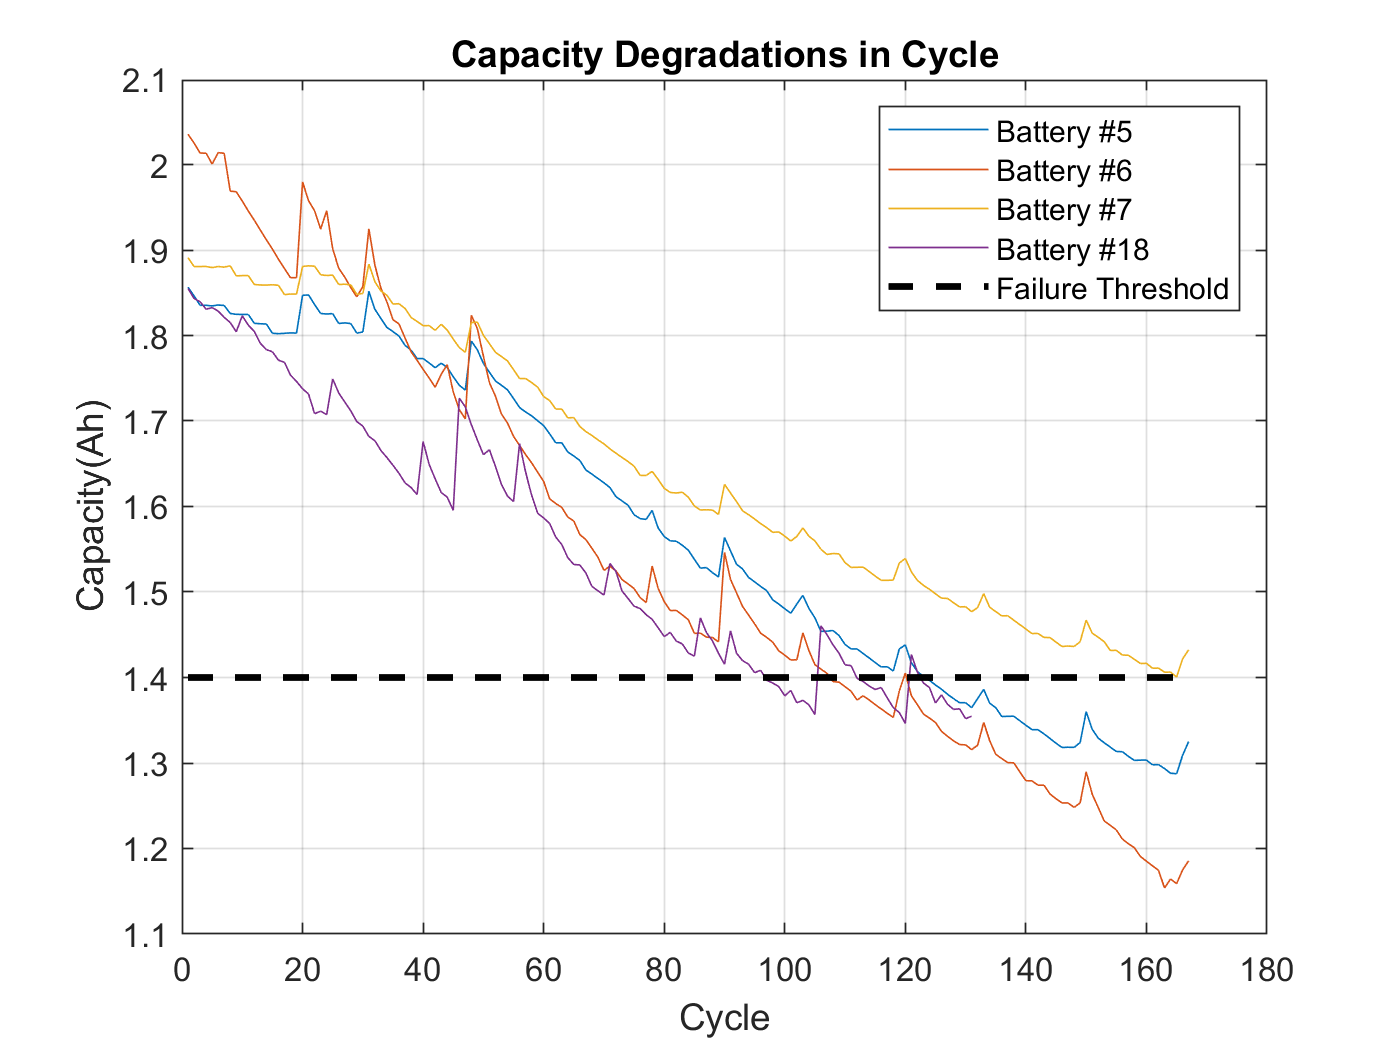

%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

% modify ohm   20 -> 30
result_05(1:30,ohmIdx) = nan;
result_06(1:30,ohmIdx) = nan;
% no gen
% 27 30
% new data set #01 / #02
result_05(27,1)

ans = 1.8148

result_06(30,1)

ans = 1.8572


% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:27,:) ; result_06(31:end,:) ]; % 30 -> 31
result_06_05 = [ result_06(1:30,:) ; result_05(27:end,:) ];
result_05_06_patten_change = [27 31];
result_06_05_patten_change = [30 27];

result_05_06_all = [ result_05 ; result_06 ];
capacity56 = result_05_06(:,1);
capacity65 = result_06_05(:,1);
capacity_all = result_05_06_all(:,1);


%% create vector / table
    
regression_vector_05 = [ ...
    result_05(:, cCcEndTimeSecIdx ) ...
    result_05(:, pattern_dVoltIdx ) ...
    result_05(:, capacityIdx ) ] ;

regression_vector_06 = [ ...
    result_06(:, cCcEndTimeSecIdx ) ...
    result_06(:, pattern_dVoltIdx ) ...
    result_06(:, capacityIdx ) ] ;


regression_vector_05_06_all = [ ...
    result_05_06_all(:, cCcEndTimeSecIdx ) ...
    result_05_06_all(:, pattern_dVoltIdx ) ...
    result_05_06_all(:, capacityIdx ) ] ;

regression_vector_05_06 = [ ...
    result_05_06(:, cCcEndTimeSecIdx ) ...
    result_05_06(:, pattern_dVoltIdx ) ...
    result_05_06(:, capacityIdx ) ] ;

regression_vector_06_05 = [ ...
    result_06_05(:, cCcEndTimeSecIdx ) ...
    result_06_05(:, pattern_dVoltIdx ) ...
    result_06_05(:, capacityIdx ) ] ;

% works
regression_table_05 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_06 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05_06 = array2table(regression_vector_05_06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_06_05 = array2table(regression_vector_06_05,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05_06_all = array2table(regression_vector_05_06_all,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

    
% https://kr.mathworks.com/help/matlab/ref/cell2table.html    
% works
%{
regression_table_5 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','capacity'});

regression_table_6 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','capacity'});
%}


% https://people.duke.edu/~rnau/arimrule.htm
% https://github.com/KevinChngJY/timeseriesinmatlab

% https://kr.mathworks.com/help/econ/specify-ar-models.html
X5 = regression_vector_05(:,1);
X5 = X5./1200 ; % sec to hour
Y5 = regression_vector_05(:,3);
U5 = regression_vector_05(:,2);

Y6 = regression_vector_06(:,3);
U6 = regression_vector_06(:,2);

Y56 = regression_vector_05_06(:,3);
U56 = regression_vector_05_06(:,2);

Y65 = regression_vector_06_05(:,3);
U65 = regression_vector_06_05(:,2);

ARIMA 자료 

[https://kr.mathworks.com/help/predmaint/ug/predict-remaining-cycle-life-of-batteries-from-initial-operation-data.html](https://kr.mathworks.com/help/predmaint/ug/predict-remaining-cycle-life-of-batteries-from-initial-operation-data.html)

# 초기 작동 데이터에서 배터리 사이클 수명 예측

[https://kr.mathworks.com/help/predmaint/ug/nonlinear-state-estimation-of-a-degrading-battery-system.html](https://kr.mathworks.com/help/predmaint/ug/nonlinear-state-estimation-of-a-degrading-battery-system.html)

# 성능 저하 중인 배터리 시스템의 비선형 상태 추정

[https://kr.mathworks.com/help/predmaint/ug/remaining-useful-life-estimation-using-convolutional-neural-network.html](https://kr.mathworks.com/help/predmaint/ug/remaining-useful-life-estimation-using-convolutional-neural-network.html)

# Remaining Useful Life Estimation using Convolutional Neural Network

[https://www.mdpi.com/1996-1073/11/4/820/htm#](https://www.mdpi.com/1996-1073/11/4/820/htm#)

settings

Open AccessArticle

# Novel Approach for Lithium-Ion Battery On-Line Remaining Useful Life Prediction Based on Permutation Entropy

[https://github.com/danzhaozju/Energy-Revenue-Optimizing/blob/master/Final%20Report.pdf](https://github.com/danzhaozju/Energy-Revenue-Optimizing/blob/master/Final%20Report.pdf)

[https://github.com/xingliuUT/battery_planner](https://github.com/xingliuUT/battery_planner)

# 가우시안 프로세스 

# 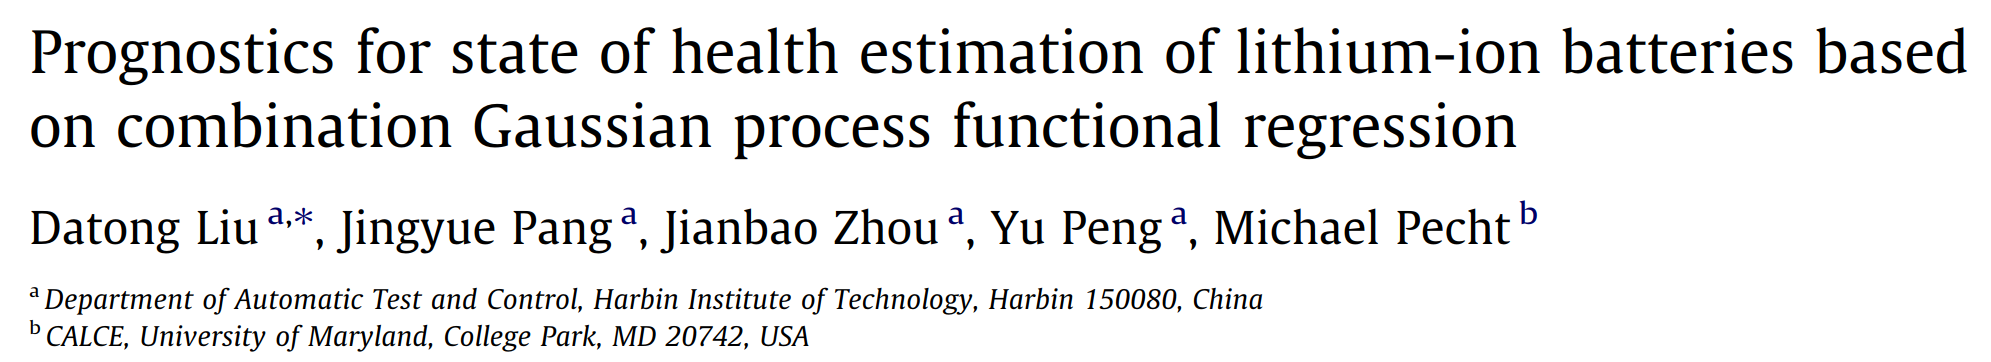

# 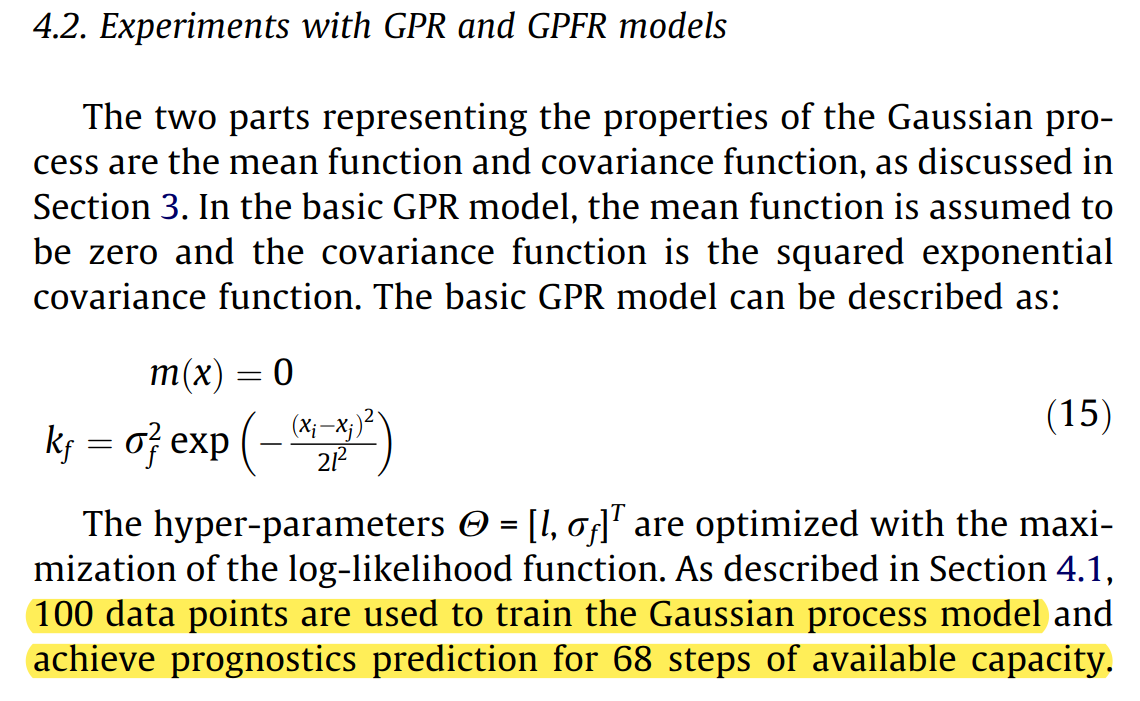

%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];

%{
BAT = Y56;
BAT_NAME = 'Y56';
pattern_change_index =27;

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;

BAT = Y5;
BAT_NAME = 'Y5';
pattern_change_index =30;

BAT = Y6;
BAT_NAME = 'Y6';
pattern_change_index =30;

%}

BAT = Y5;
BAT_NAME = 'Y5';

learning_start_index = 1;
learning_end_index = 100 ; 

%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = true;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));


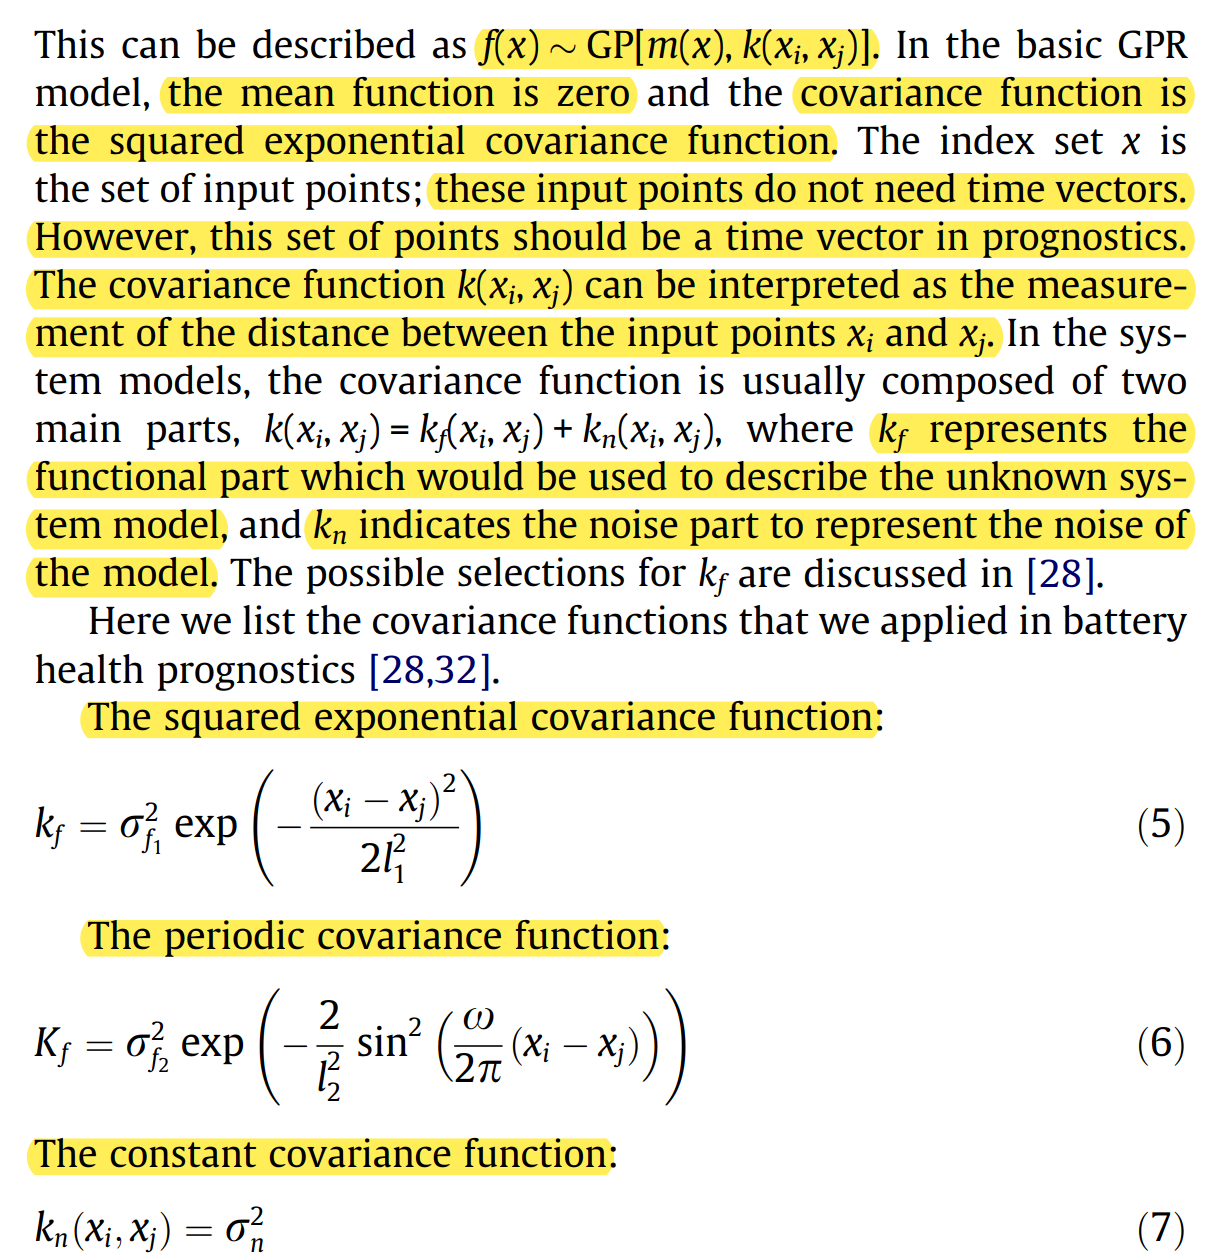

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

gprMdl1 = fitrgp(x_observed,y_observed1,...
    "BasisFunction","linear",...
    "KernelFunction" , "squaredexponential" ,...
    "FitMethod" , "exact" , ...
    "PredictMethod" , "exact" ,...
    "Standardize" , 1 );

%{
    "KernelFunction"2 , "perodic" ,...
    "KernelFunction"3 , "constant" ,...
%}

[ypred1,~,yint1] = predict(gprMdl1,idxest');


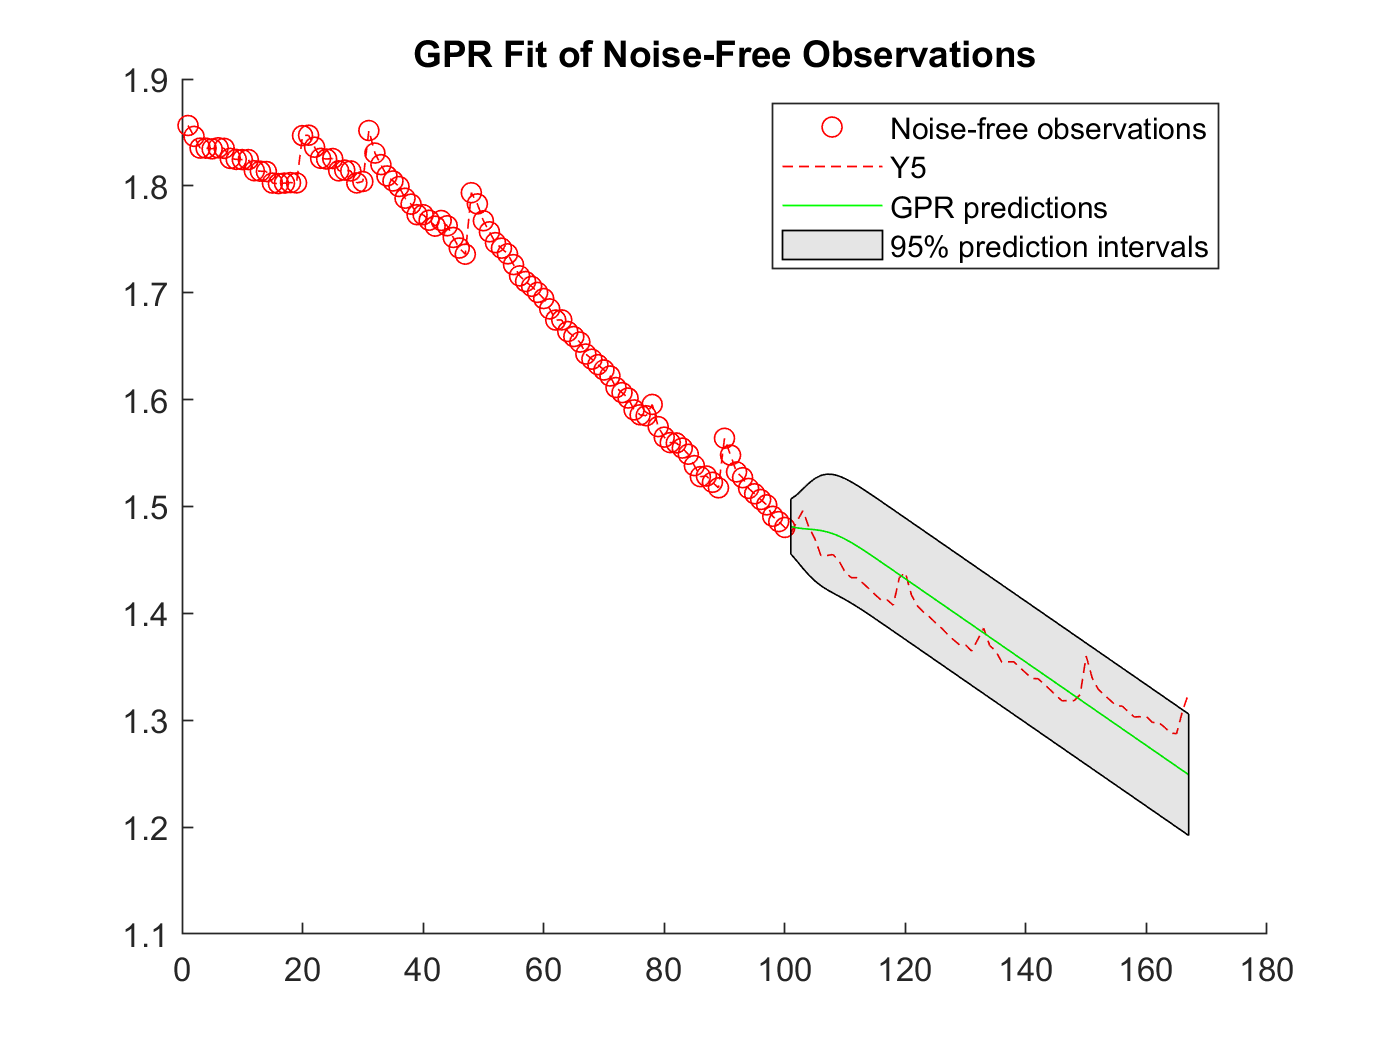

figure
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

# Fit GPR Model Using Custom Kernel Function

`openExample('stats/FitGPRModelUsingCustomKernelFunctionExample')`

Define the squared exponential kernel function as a custom kernel function.

You can compute the squared exponential kernel function as 


$$k(x_i,x_j|\theta) = \sigma_f^2 \exp\left (-\frac{1}{2}
\frac{(x_i-x_j)^T(x_i-x_j)}{\sigma_l^2}\right ),$$


where $\sigma_f$ is the signal standard deviation, $\sigma_l$ is the length scale. Both $\sigma_f$ and $\sigma_l$ must be greater than zero. This condition can be enforced by the unconstrained parametrization, $\sigma_l = \exp(\theta(1))$ and $\sigma_f = \exp(\theta(2))$, for some unconstrained parametrization vector $\theta$.

Hence, you can define the squared exponential kernel function as a custom kernel function as follows:

kfcn = @(XN,XM,theta) (exp(theta(2))^2)*exp(-(pdist2(XN,XM).^2)/(2*exp(theta(1))^2));

Here `pdist2(XN,XM).^2` computes the distance matrix. 

Fit a GPR model using the custom kernel function, `kfcn`. Specify the initial values of the kernel parameters (Because you use a custom kernel function, you must provide initial values for the unconstrained parametrization vector, `theta`).

theta0 = [1.5,0.2];

gprMdl_custom = fitrgp(x_observed,y_observed1,'KernelFunction',kfcn,'KernelParameters',theta0);

`fitrgp` uses analytical derivatives to estimate parameters when using a built-in kernel function, whereas when using a custom kernel function it uses numerical derivatives.

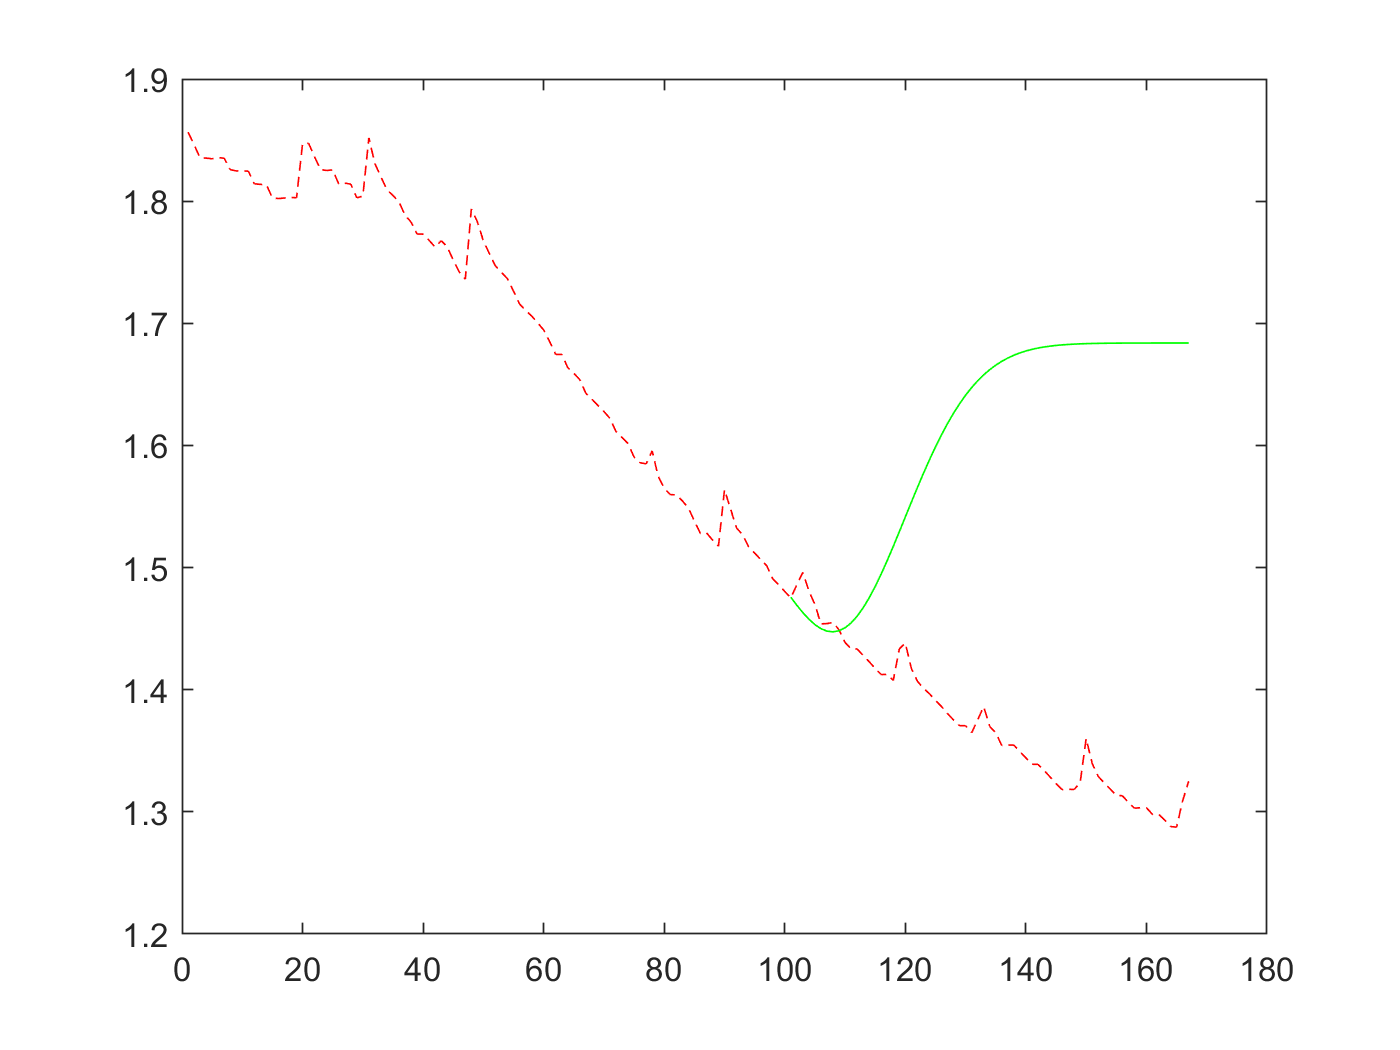


[ypred1,~,yint1] = predict(gprMdl_custom,idxest');
figure
plot(idxall', Y5,'--r')
hold on
plot(idxest',ypred1,'g')   

Compute the resubstitution loss for this model. 

L = resubLoss(gprMdl)

L = 1.1900e-04

Fit the GPR model using the built-in squared exponential kernel function option. Specify the initial values of the kernel parameters (Because you use the built-in custom kernel function and specifying initial parameter values, you must provide the initial values for the signal standard deviation and length scale(s) directly). 

sigmaL0 = exp(1.5);
sigmaF0 = exp(0.2);
gprMdl2 = fitrgp(x_observed,y_observed1,'KernelFunction','squaredexponential','KernelParameters',[sigmaL0,sigmaF0]);

Compute the resubstitution loss for this model. 

L2 = resubLoss(gprMdl2)

L2 = 1.1900e-04

The two loss values are the same as expected.

*Copyright 2012 The MathWorks, Inc.*

o Parameter estimation: FitMethod = Exact, Optimizer = quasinewton

|=====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  | CG TERM |     RHO     |  TRUST RAD  | ACCEPT |
|=====================================================================================================|
|        0 |   4.09512e+01 |   3.579e+01 |   6.927e-01 |   CONV  |   1.619e+00 |   2.449e+00 |   YES  |
|        1 |   4.09512e+01 |   3.579e+01 |   7.809e-01 |   CONV  |  -7.777e-01 |   2.449e+00 |    NO  |
|        2 |   3.50716e+01 |   1.355e+01 |   2.243e-01 |   CONV  |   1.434e+00 |   1.225e+00 |   YES  |
|        3 |   3.41413e+01 |   6.449e+00 |   1.620e-01 |   CONV  |   7.715e-01 |   1.225e+00 |   YES  |
|        4 |   3.39030e+01 |   2.709e+00 |   4.512e-02 |   CONV  |   1.334e+00 |   1.225e+00 |   YES  |
|        5 |   3.39030e+01 |   2.709e+00 |   1.225e+00 |  EXACT  |  -6.710e-01 |   1.225e+00 |    NO

gpr =   RegressionGP
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 100
           KernelFunction: @mykernel
        KernelInformation: [1×1 struct]
            BasisFunction: 'Constant'
                     Beta: 2.6593
                    Sigma: 0.2245
        PredictorLocation: []
           PredictorScale: []
                    Alpha: [100×1 double]
         ActiveSetVectors: [100×2 double]
            PredictMethod: 'Exact'
            ActiveSetSize: 100
                FitMethod: 'Exact'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [100×1 logical]
            LogLikelihood: -31.9759
         ActiveSetHistory: []
           BCDInformation: []


  Properties, Methods


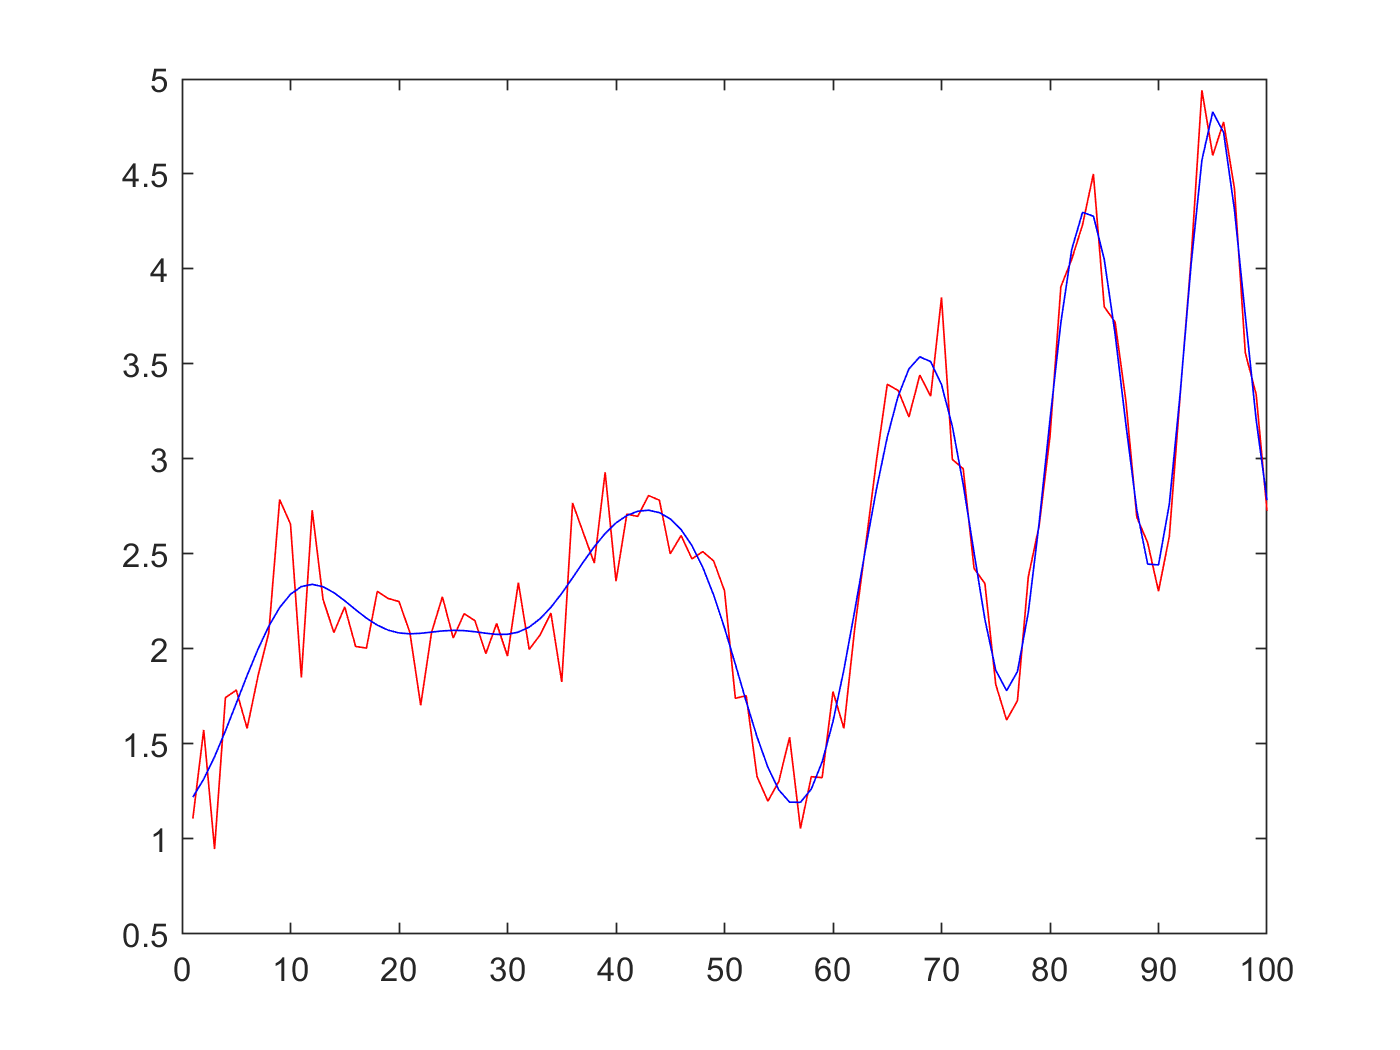

ans = struct with fields:
                    Name: 'CustomKernel'
        KernelParameters: [5×1 double]
    KernelParameterNames: {5×1 cell}


ans = 5×1 cell array
    {'Theta1'}
    {'Theta2'}
    {'Theta3'}
    {'Theta4'}
    {'Theta5'}


thetaHat =     3.6120
   -2.7219
   -2.5892
   -0.0940
   -0.5679


testcustomkernel();

GP 로는 잘 동작하지 않는다.

mean function 이 정확해야 하나 패넡 변화를 인지하더라도 mean function 이 선형적이 아니라서 결국 예측에 실패한다.

따라서 GP는 패턴별로 여러 데이타셋을 가지고 테스트 해야 의미가 있는 것 같다. 

change point들을 계속 검색하고

선형 회귀의 가중치를 이전의 측정값에 가중치를 줄이고 

최근 변화된 데이타를 가중치를 더 주면 

GP를 사요할 경우 계속 추정치가 현실에 맞게 변화될 것이다.

이는 Kalman Filter랑 비슷하다.

여기서 평가는 학습구간과 예측구간이 점차 뒤로 이동하게 된다.

이에 따른 평가를 해야 한다.

다시 보면 이는 LSTM 이라 같은 결과를 가져올 것 같다. 

관측값을 처음부터  패턴 변경 후 10번째 까지로 하자

learning_start_index = 1;

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = true;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

%{
gprMdl1 = fitrgp(x_observed,y_observed1,"Basis","constant","KernelFunction" , "squaredexponential" , ...
    'OptimizeHyperparameters','auto',"FitMethod" , "exact" , "PredictMethod" , "exact" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"Basis","constant","KernelFunction" , "squaredexponential" , ...
    'OptimizeHyperparameters','auto',"FitMethod" , "exact" , "PredictMethod" , "exact" , "Standardize" , 1 );
%}

[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

관측값을 전체로 하면 실제값과 예측값이 같다.

use_just_observed = false;

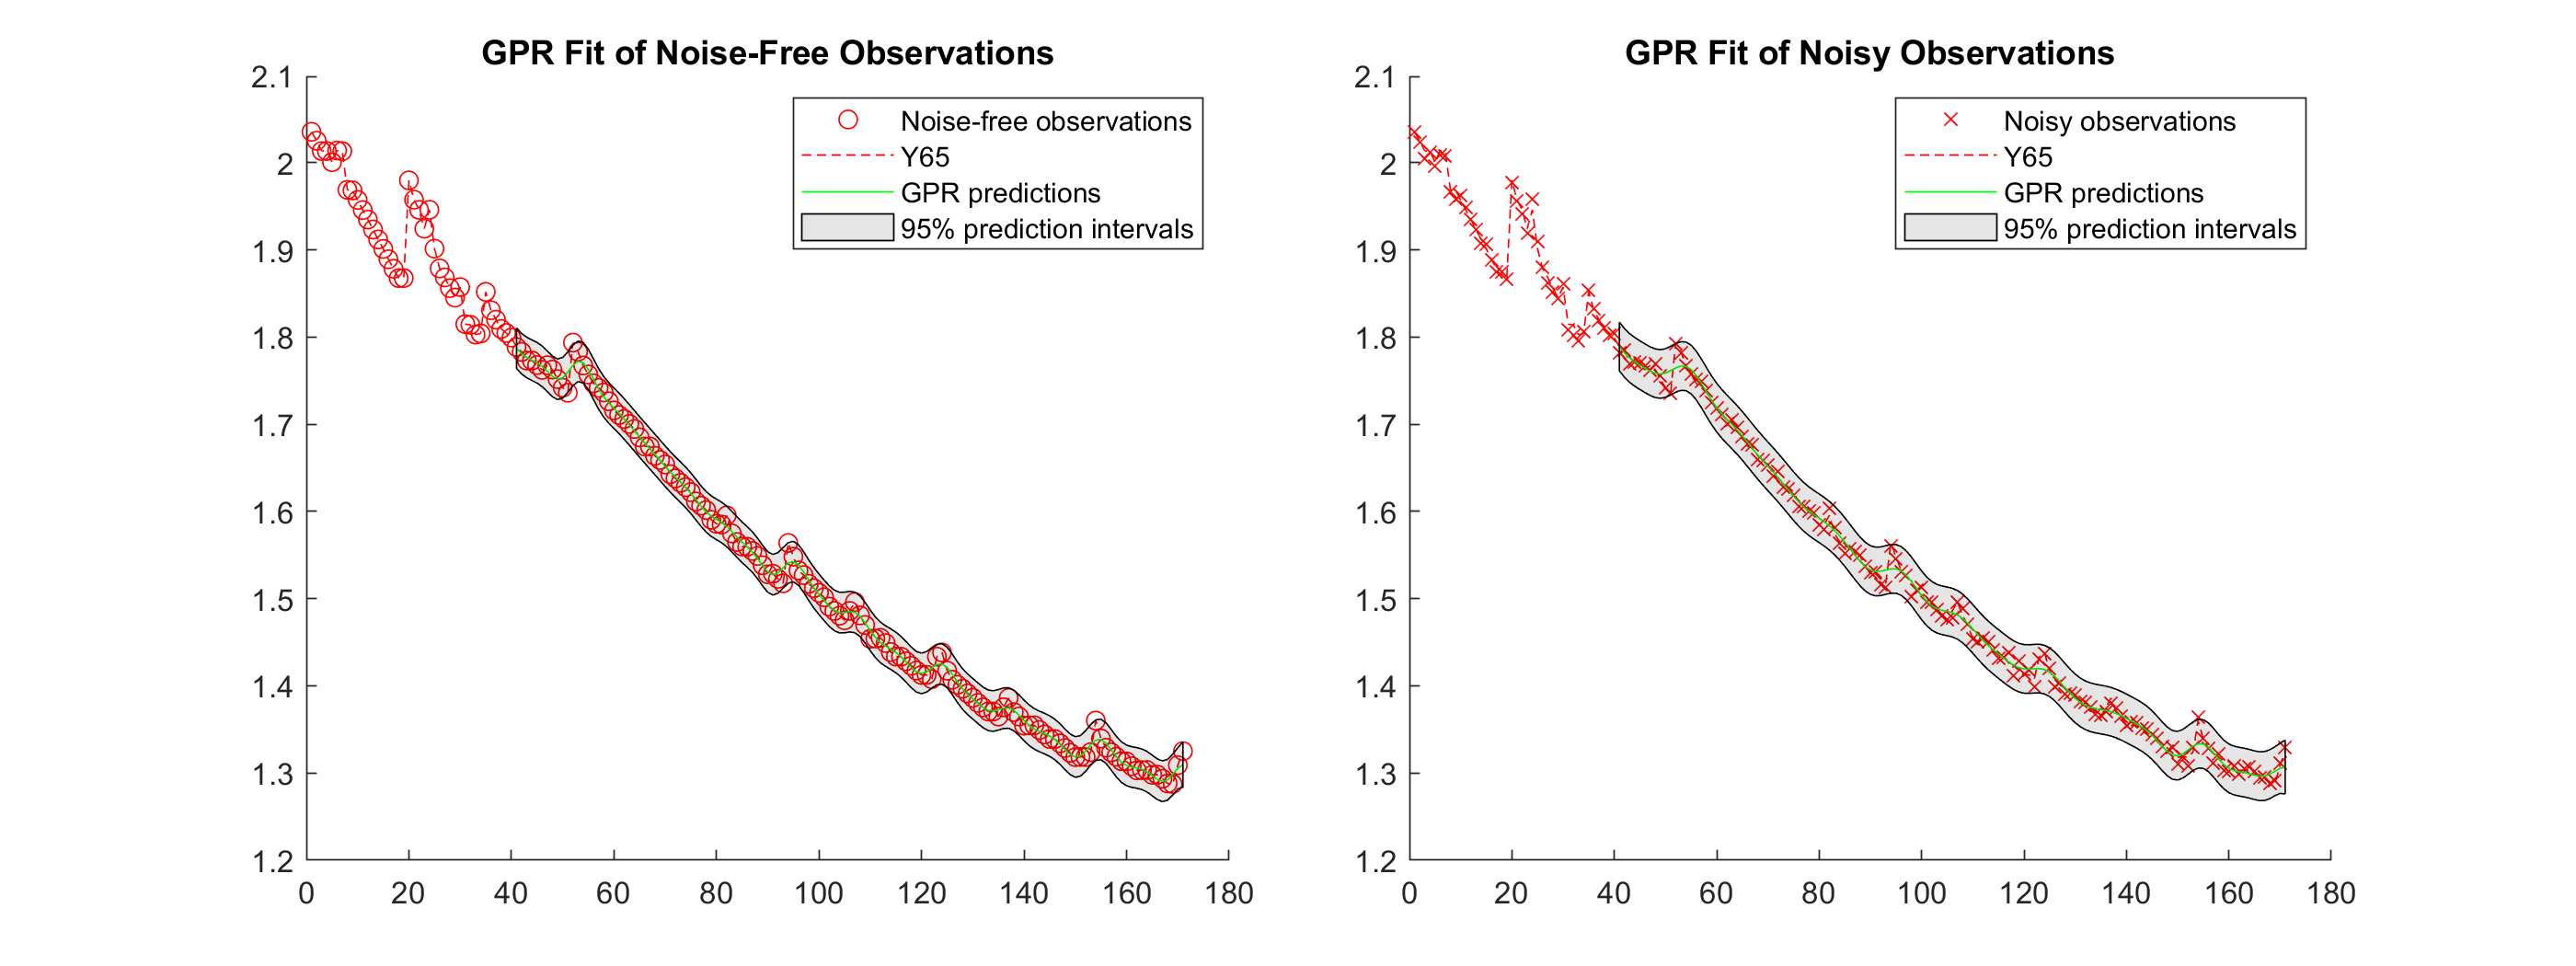

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;



%learning_start_index = 1;
learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP는 관측값이 작은 경우에서 큰 경우로 변경되면서 예측력이 우수해진다.  => 베이지안 기반 가우시안 프로세스

작은 관측값으로 먼저 피팅하고 새 관측값을 추가해보자.

1 6 11 16 22 26 31 36 41

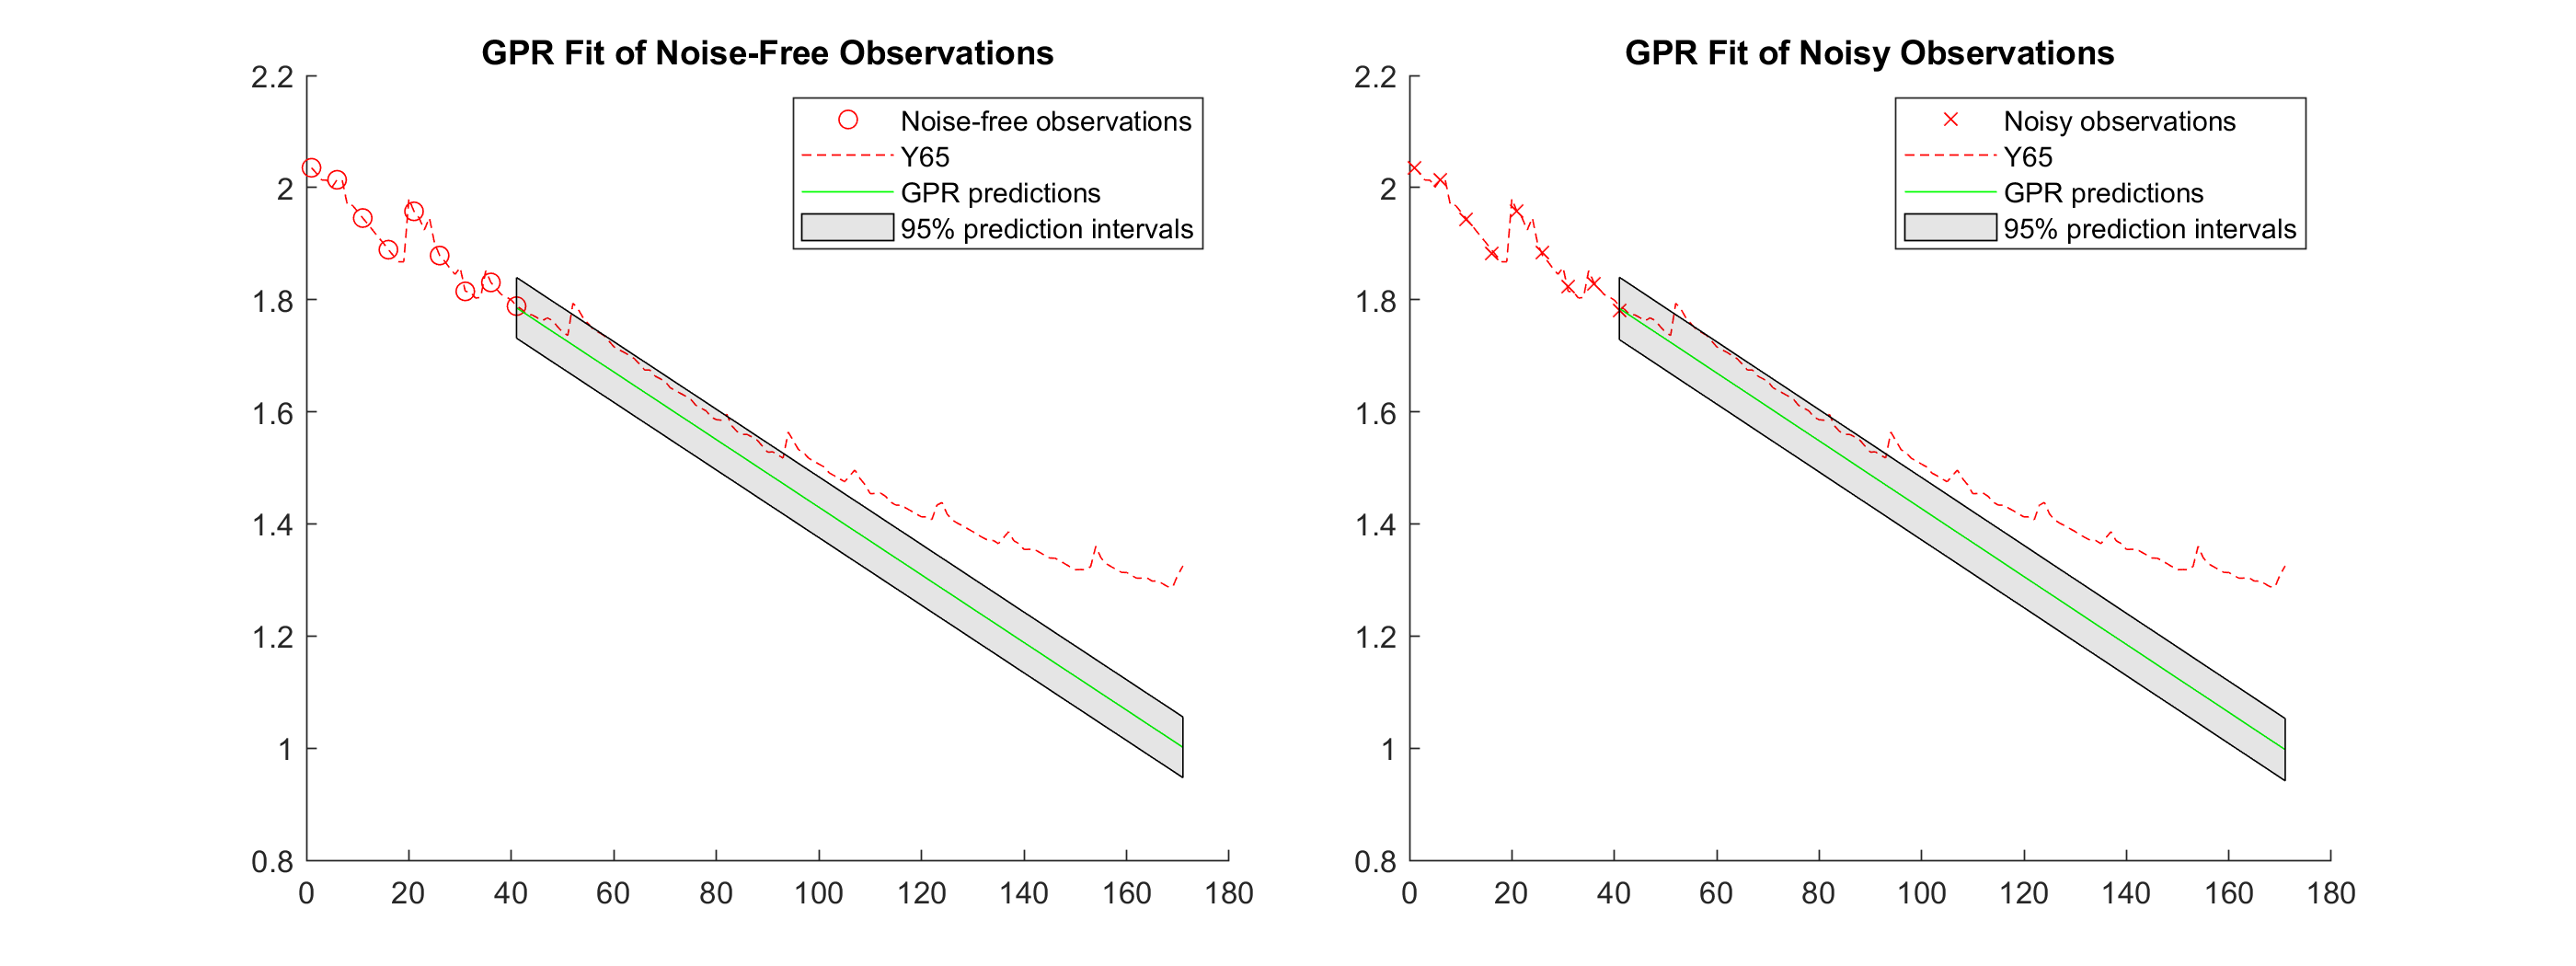

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;
BAT_sample = BAT(1:5:end); %21
%x_sample = [1:5:length(BAT)];
x_sample = [1:5:41]; % 41 51 61

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

    x_observed = x_sample';
    y_observed1 =  BAT(x_sample);    

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

%}
gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP는 관측값이 작은 경우에서 큰 경우로 변경되면서 예측력이 우수해진다.  => 베이지안 기반 가우시안 프로세스

작은 관측값으로 먼저 피팅하고 새 관측값을 추가해보자.

변경된 시점부터 다시 시작한다.

31 36 41

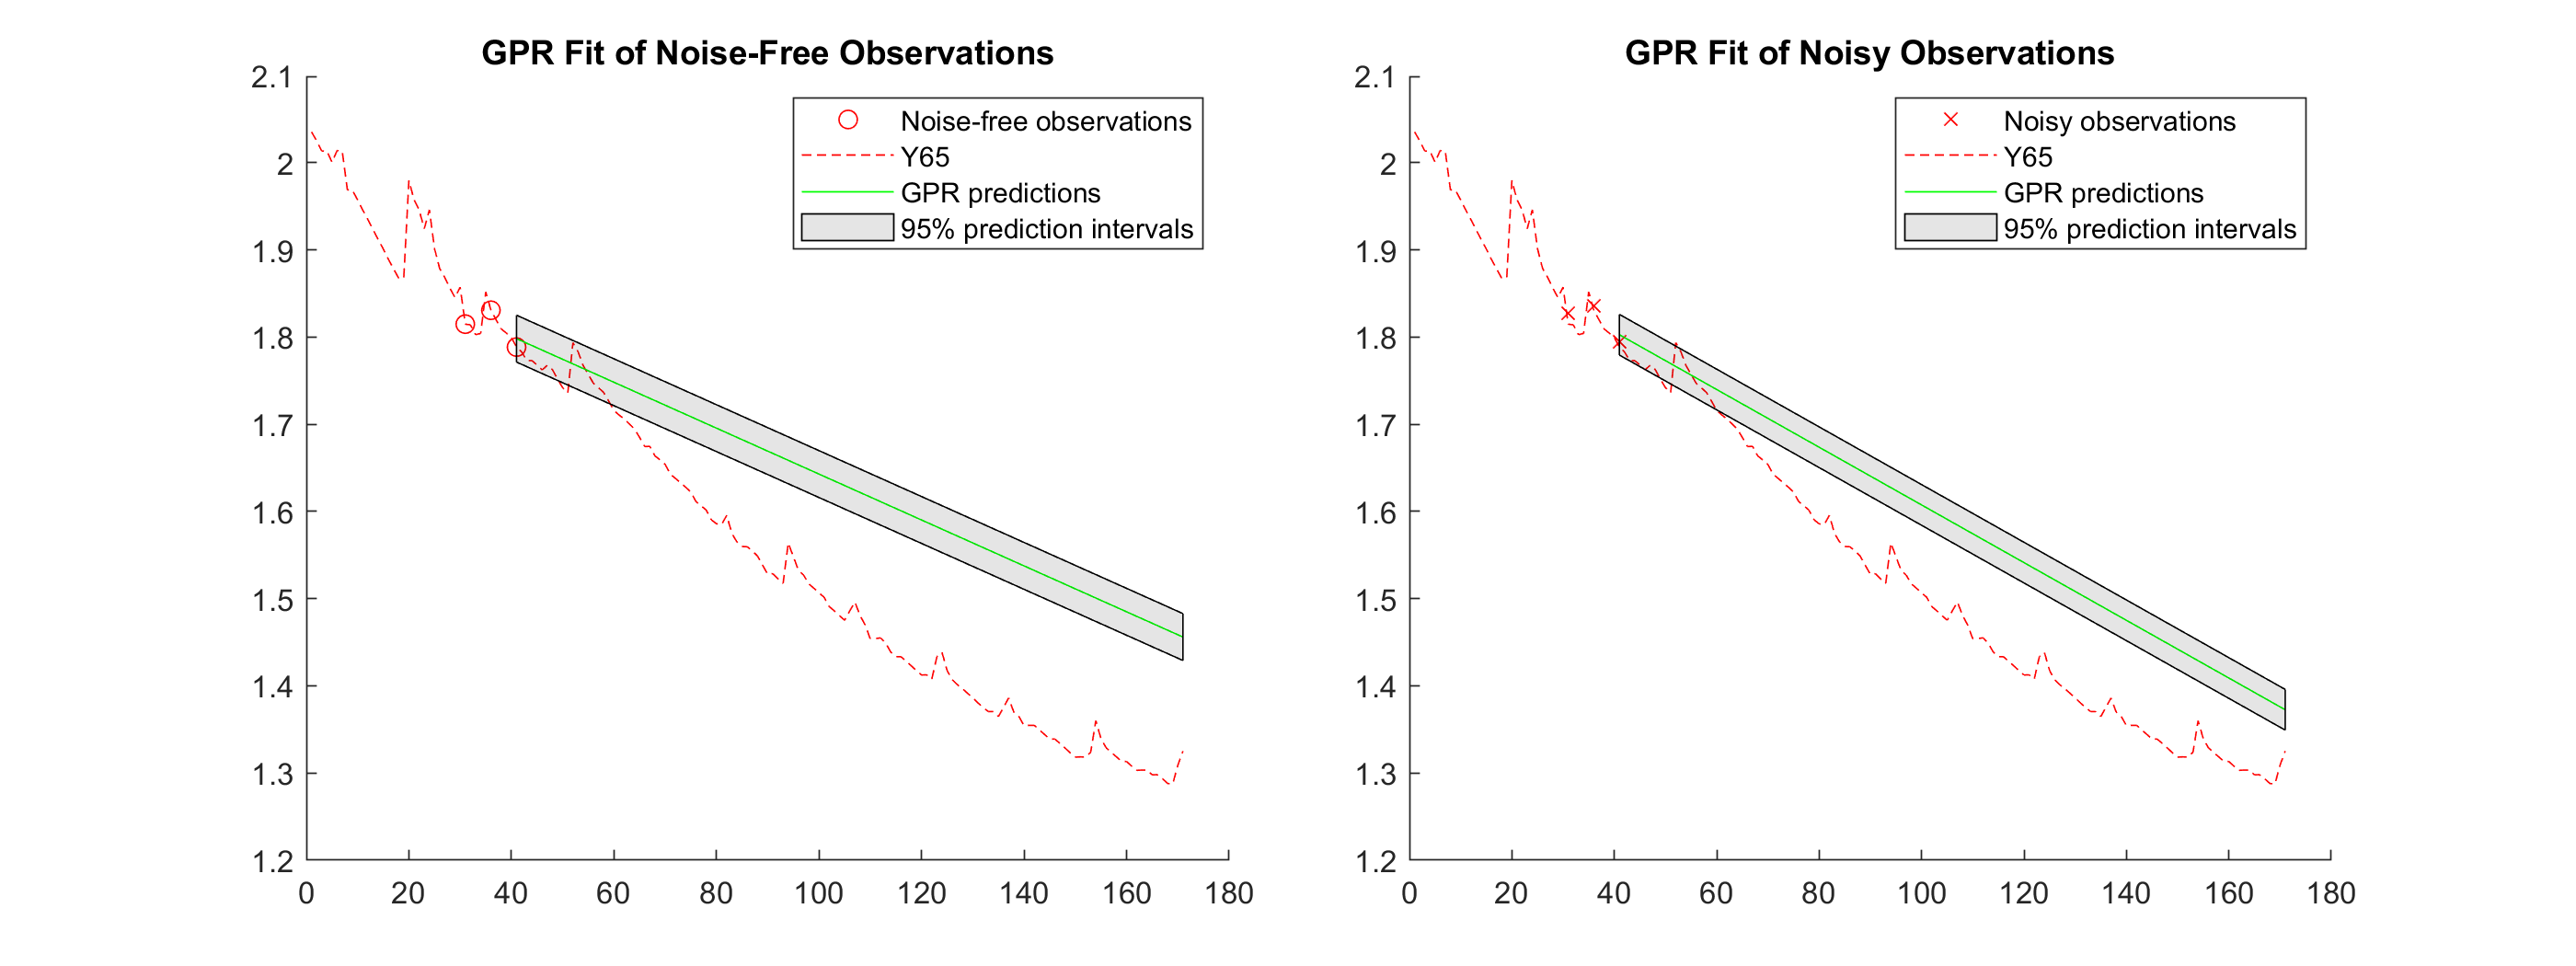

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;
BAT_sample = BAT(1:5:end); %21
%x_sample = [1:5:length(BAT)];
x_sample = [31 36 41]; % 41 51 61

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

    x_observed = x_sample';
    y_observed1 =  BAT(x_sample);    

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

%}
gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')